clear ;
close all;


tic
load ryan3_data.mat
toc 

Elapsed time is 1.380111 seconds.


load ryan3_model_gen_CC_RUL.mat

% https://kr.mathworks.com/help/matlab/ref/load.html
%load('ryan3_gen_data.mat','battery_dataset')

# 선형회귀

coeff = mdl_Ic_RUL.Coefficients.Estimate

coeff =     0.3517
   -0.0478
   -0.0324
   -0.2161
    0.1623
   -0.2199
   -0.0569
   -0.0843
    0.2115
   -0.2393


x_trainValid_Ic_RUL(1,:)

ans =     0.4398    0.5497    0.5498    0.5497    0.5497    0.5497    0.5497    0.5497    0.5497    0.5498    0.5497    0.5497    0.5497    0.5497    0.3625    0.1249    0.1249    0.0124         0         0


training set 에서는 정말 잘 동작함.

RMSE 가 정말 작다.

yhat = x_trainValid_Ic_RUL*coeff(2:21)+coeff(1)

yhat =     0.4490
    0.4577
    0.4475
    0.4580
    0.4433
    0.4403
    0.4403
    0.4385
    0.4368
    0.4355


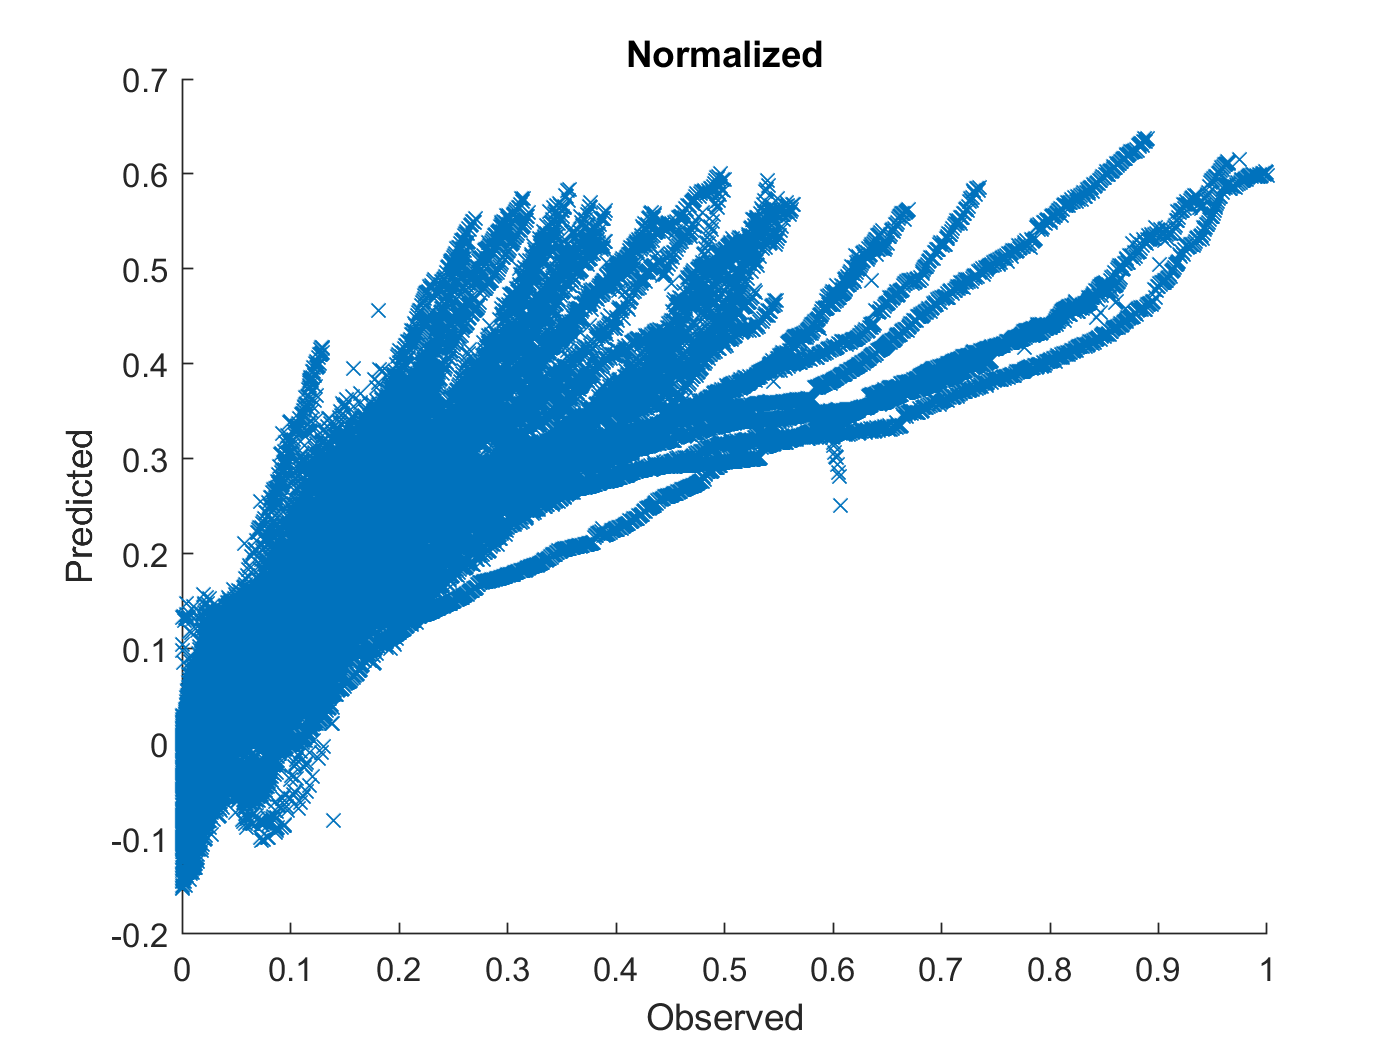

figure
hold on
plot(y_trainValid_Ic_RUL,yhat,'x')
xlabel("Observed")
ylabel("Predicted")
hold off
title 'Normalized'

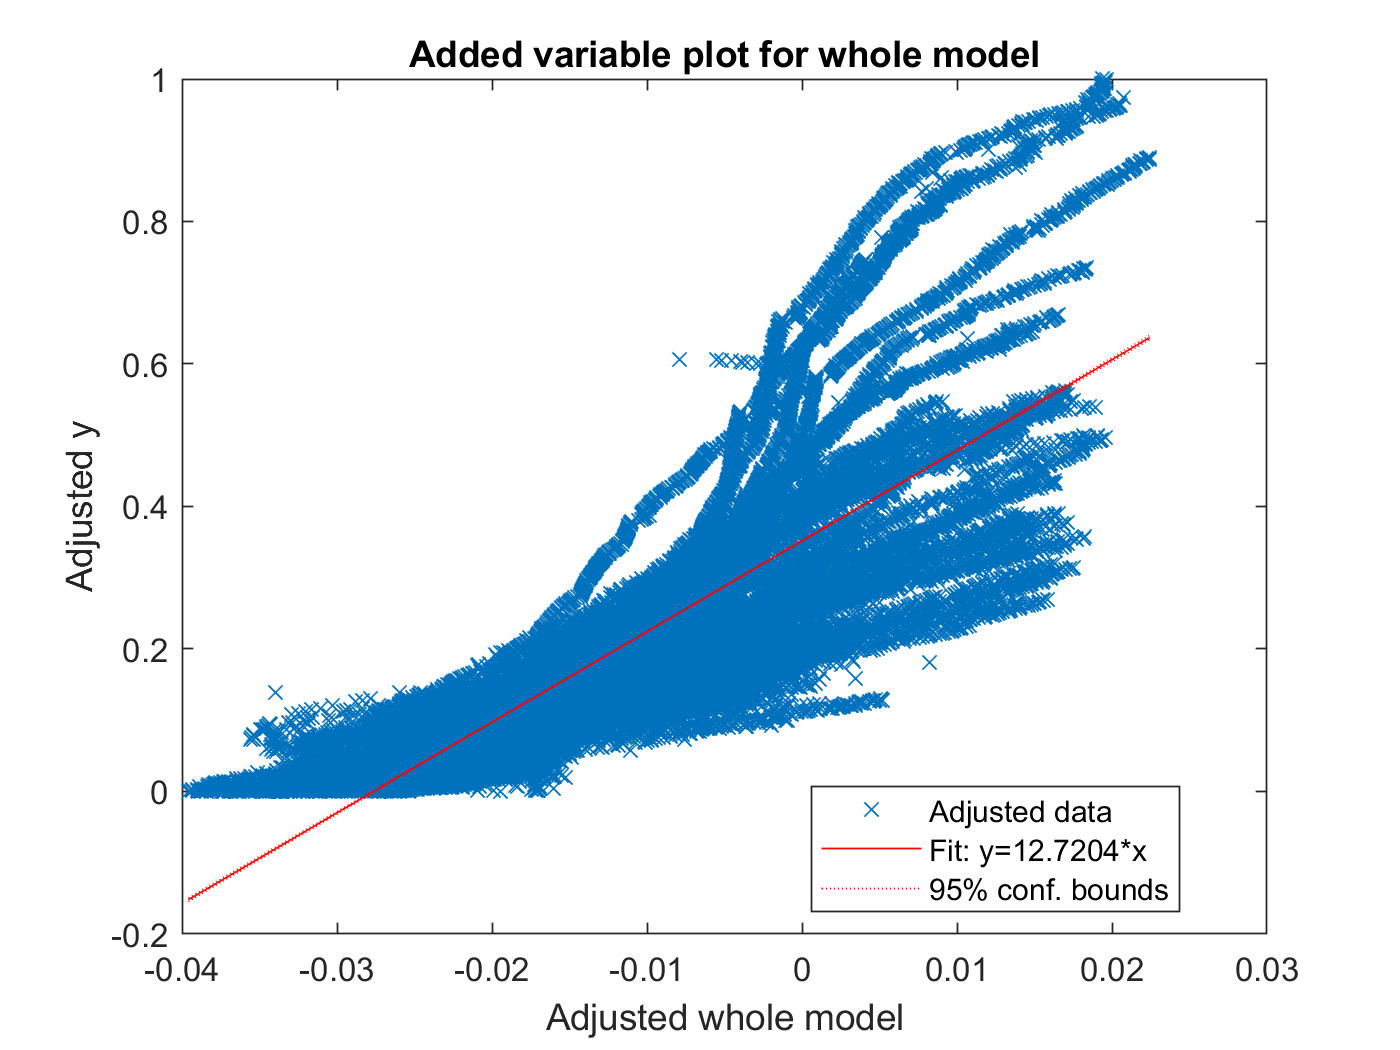


%capHat = Ic(1)

plot(mdl_Ic_RUL)

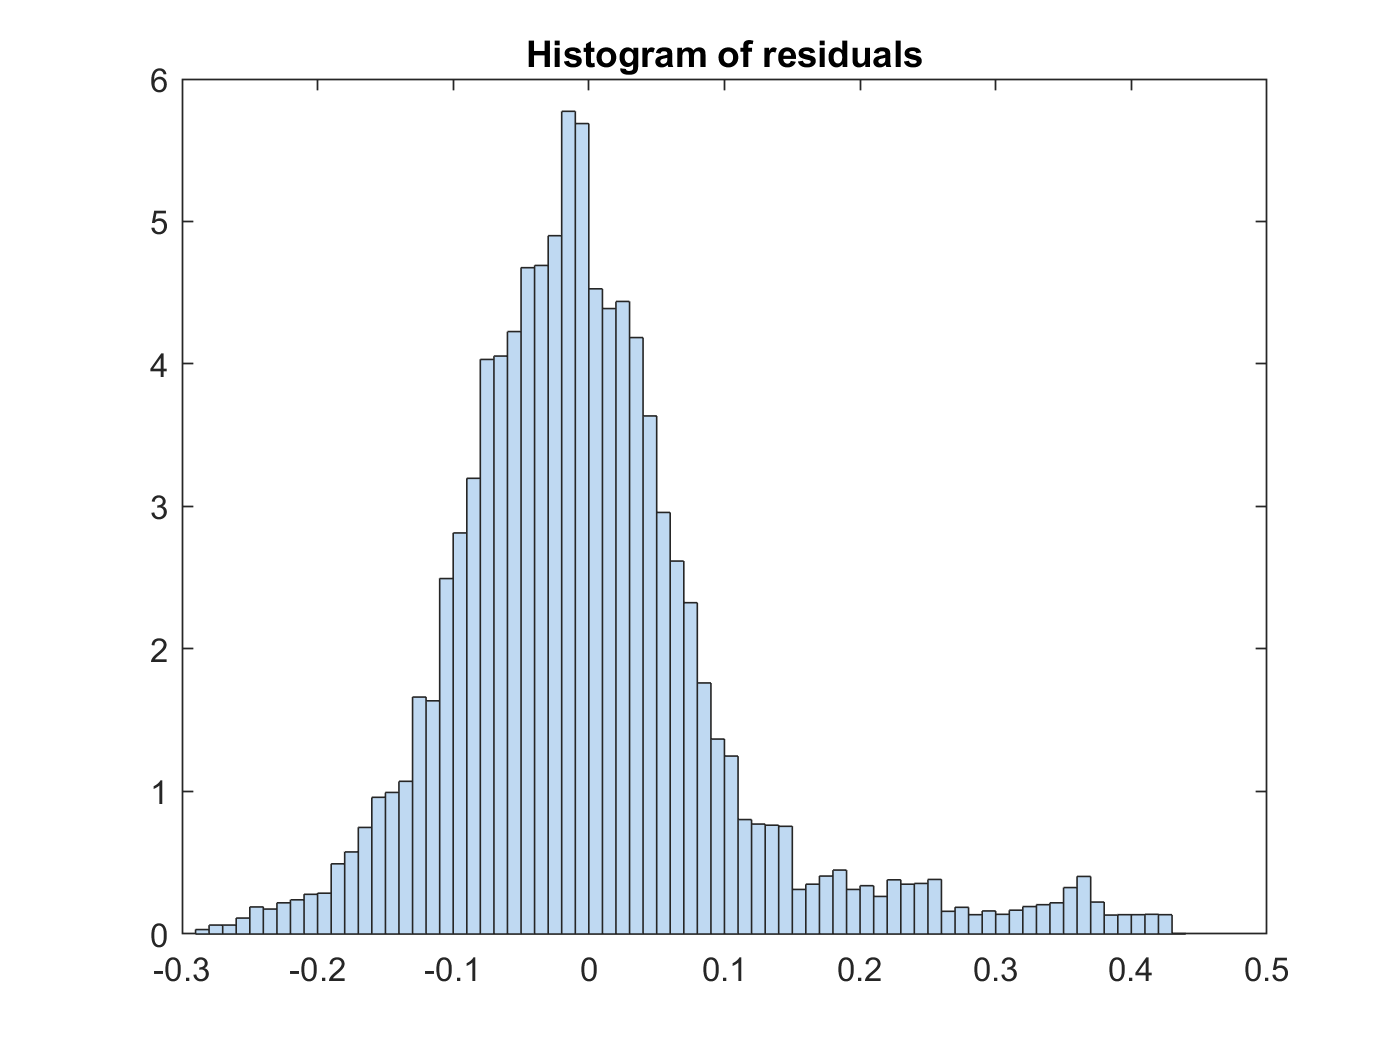

plotResiduals(mdl_Ic_RUL)




% yfit = predict(mdl_Ic_RUL,Ic)
yfit = predict(mdl_Ic_RUL,x_trainValid_Ic_RUL)

yfit =     0.4490
    0.4577
    0.4475
    0.4580
    0.4433
    0.4403
    0.4403
    0.4385
    0.4368
    0.4355


yfit_test = predict(mdl_Ic_RUL,x_test_Ic_RUL)

yfit_test =     0.3780
    0.3759
    0.3743
    0.3705
    0.3698
    0.3690
    0.3657
    0.3647
    0.3633
    0.3602




y= y_trainValid_Ic_RUL

y =     0.3650
    0.3641
    0.3632
    0.3624
    0.3615
    0.3607
    0.3598
    0.3590
    0.3581
    0.3573


y_test_Ic_RUL

y_test_Ic_RUL = 	1.0e+03 *

    0.3160
    0.3150
    0.3140
    0.3130
    0.3120
    0.3110
    0.3100
    0.3090
    0.3080
    0.3070



% denormalize
yfit = yfit * yrate_Ic_RUL + ymin_Ic_RUL;
y = y * yrate_Ic_RUL + ymin_Ic_RUL;
yfit_test = yfit_test * yrate_Ic_RUL + ymin_Ic_RUL;
y_test_Ic_RUL = y_test_Ic_RUL * yrate_Ic_RUL + ymin_Ic_RUL;


MAE = mean(abs(yfit-y))

MAE = 87.2495

adjMAE = MAE/range(y)

adjMAE = 0.0746

range(y) % y = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 1170


(y - yhat)    % Errors

ans = 	1.0e+03 *

    0.4276
    0.4265
    0.4256
    0.4245
    0.4236
    0.4226
    0.4216
    0.4206
    0.4196
    0.4186


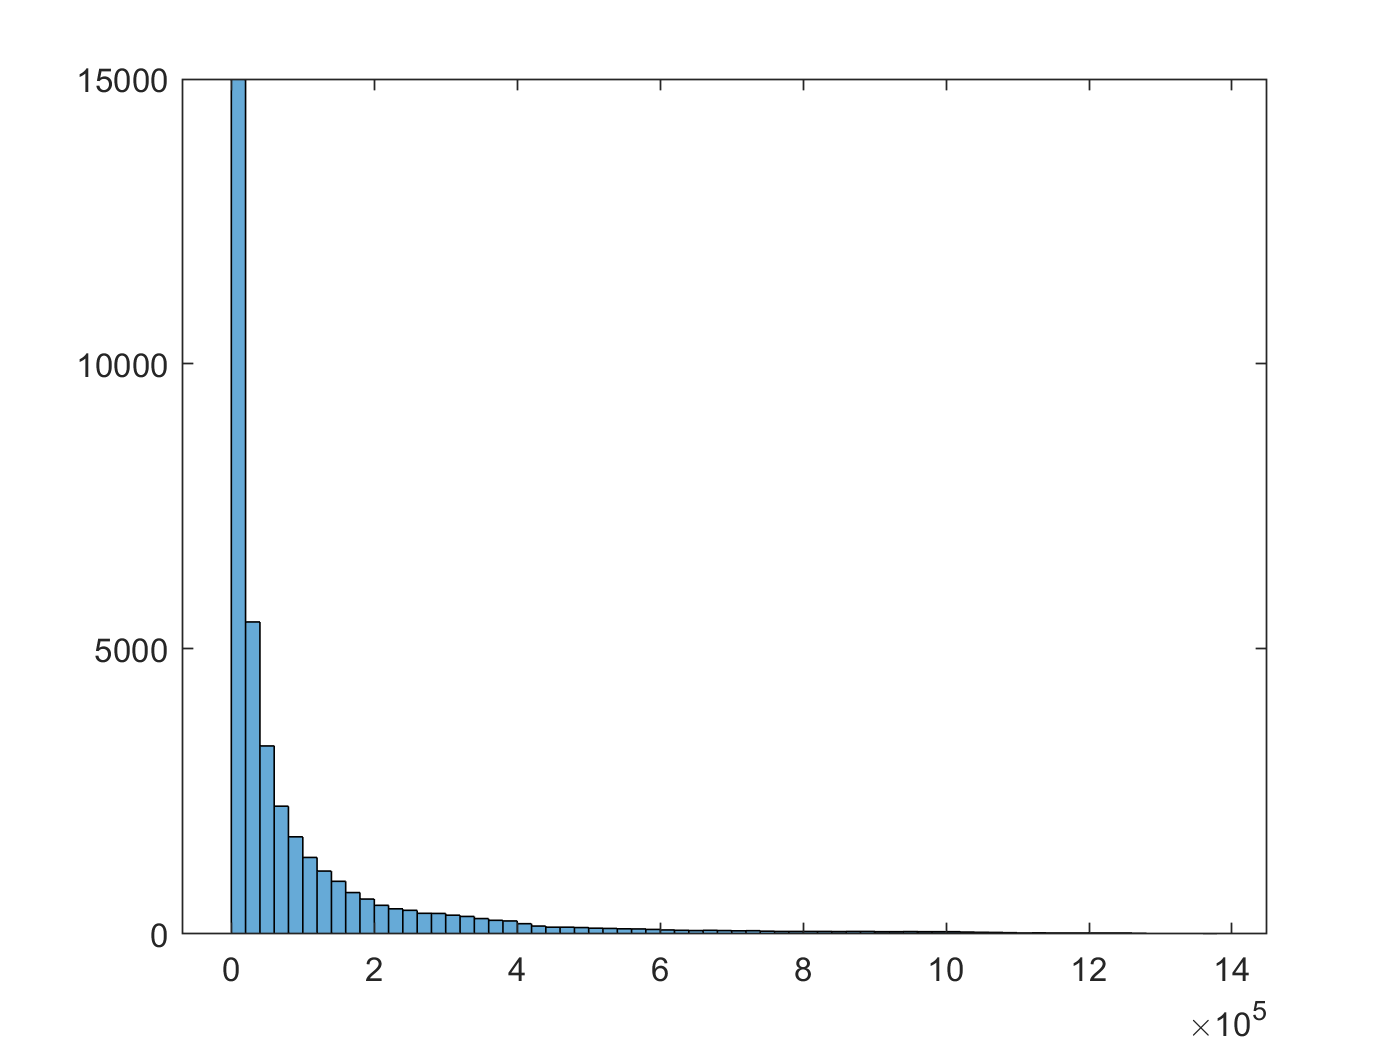

(y - yhat).^2;   % Squared Error
histogram((y - yhat).^2)

mean((y - yhat).^2);   % Mean Squared Error
RMSE = sqrt(mean((y - yhat).^2))  % Root Mean Squared Error

RMSE = 327.7725

(y_test_Ic_RUL - yfit_test) 

ans = 	1.0e+06 *

    0.3693
    0.3681
    0.3669
    0.3658
    0.3646
    0.3634
    0.3623
    0.3611
    0.3599
    0.3588


RMSE_test = sqrt(mean((y_test_Ic_RUL - yfit_test).^2))

RMSE_test = 4.1012e+05

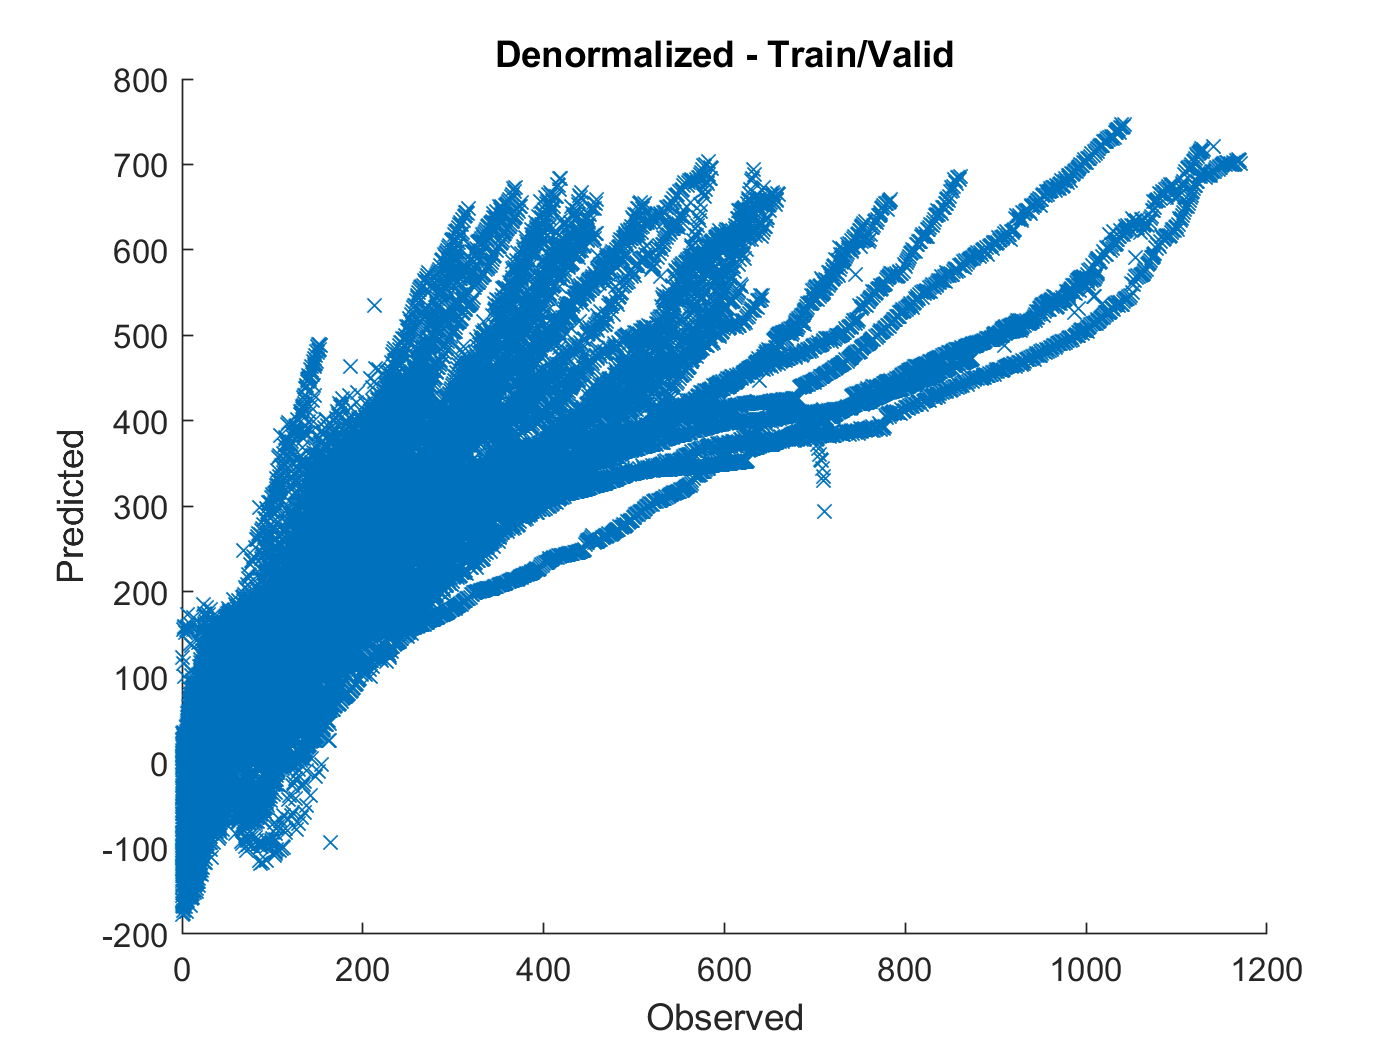


figure
hold on
plot(y,yfit,'x')
xlabel("Observed")
ylabel("Predicted")
hold off
title 'Denormalized - Train/Valid'

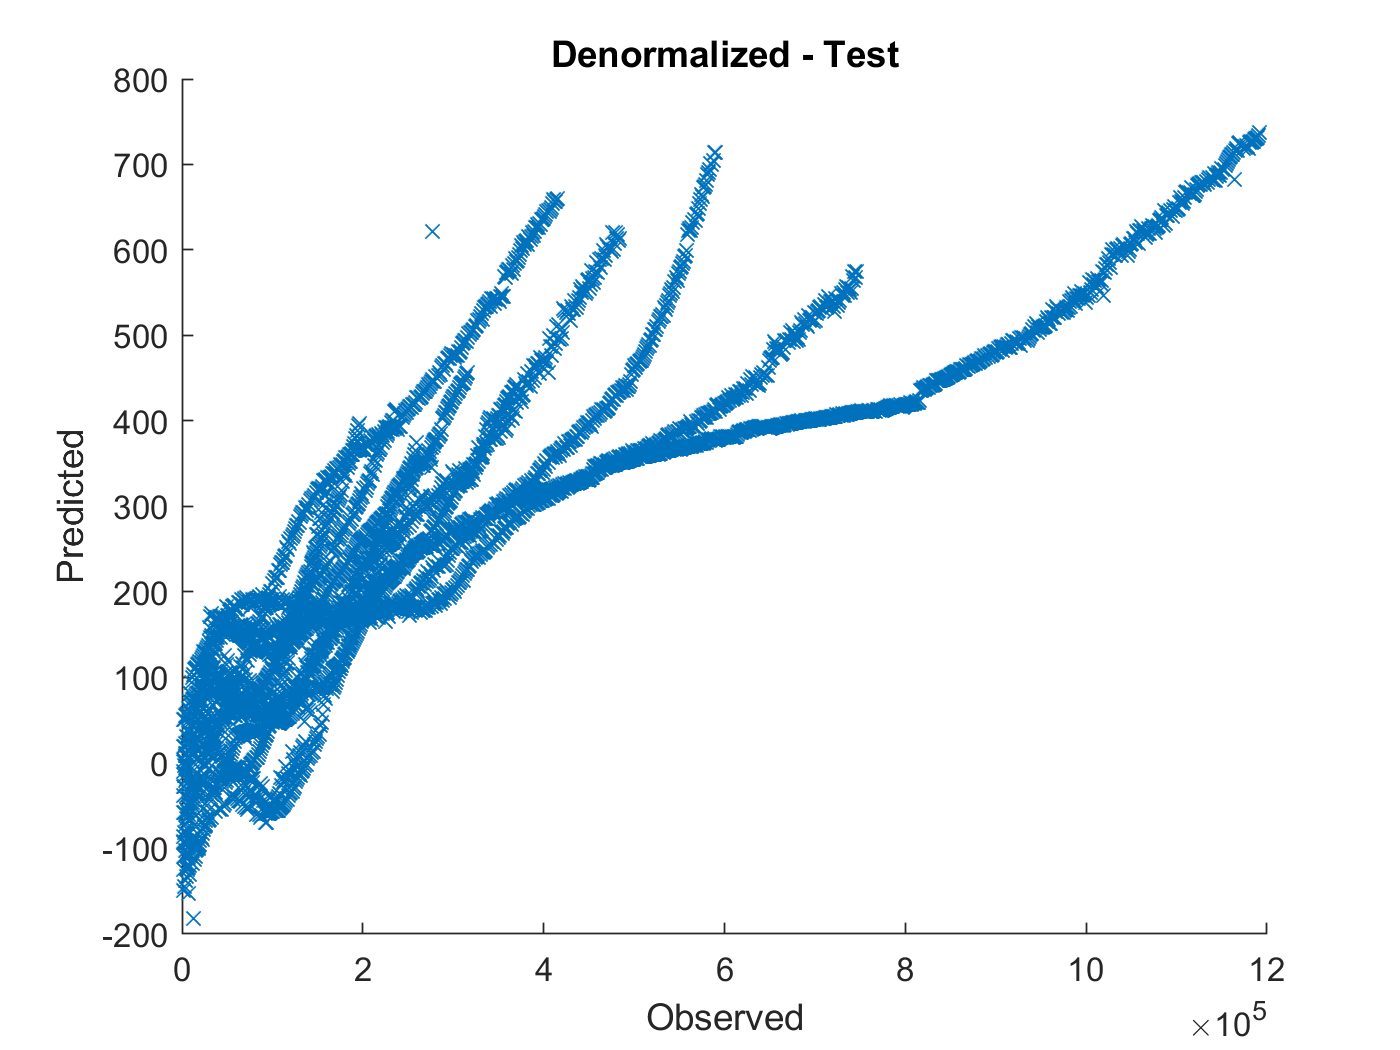


figure
hold on
plot(y_test_Ic_RUL,yfit_test,'x')
xlabel("Observed")
ylabel("Predicted")
hold off
title 'Denormalized - Test'

%xlim([0 1200]), ylim([0 1200])

% 테스트 셋에서는 예측이 전혀 안된다.


# 머신러닝을 위한 기본 설정

epoc_count = 10;
cc_input_size = 20;



# FNN


pFNN1_1 = netFNN1_1(xnorm_Ic_RUL(idxTestAll, :)');
pFNN1_2 = netFNN1_2(xnorm_Ic_RUL(idxTestAll, :)');
pFNN1_3 = netFNN1_3(xnorm_Ic_RUL(idxTestAll, :)');
pFNN2_1 = netFNN2_1(xnorm_Ic_RUL(idxTestAll, :)');
pFNN2_2 = netFNN2_2(xnorm_Ic_RUL(idxTestAll, :)');
pFNN3_1 = netFNN3_1(xnorm_Ic_RUL(idxTestAll, :)');
pFNN4_1 = netFNN4_1(xnorm_Ic_RUL(idxTestAll, :)');
pFNN5_1 = netFNN5_1(xnorm_Ic_RUL(idxTestAll, :)');

ytest = ynorm_Ic_RUL(idxTestAll, :)*yrate_Ic_RUL + ymin_Ic_RUL;
pFNN1_1_hat = pFNN1_1 * yrate_Ic_RUL + ymin_Ic_RUL;
pFNN1_2_hat = pFNN1_2 * yrate_Ic_RUL + ymin_Ic_RUL;
pFNN1_3_hat = pFNN1_3 * yrate_Ic_RUL + ymin_Ic_RUL;
pFNN2_1_hat = pFNN2_1 * yrate_Ic_RUL + ymin_Ic_RUL;
pFNN2_2_hat = pFNN2_2 * yrate_Ic_RUL + ymin_Ic_RUL;
pFNN3_1_hat = pFNN3_1 * yrate_Ic_RUL + ymin_Ic_RUL;
pFNN4_1_hat = pFNN4_1 * yrate_Ic_RUL + ymin_Ic_RUL;
pFNN5_1_hat = pFNN5_1 * yrate_Ic_RUL + ymin_Ic_RUL;


rmse_pFNN1_1_hat = sqrt(mean(( ytest' - pFNN1_1_hat ).^2))

rmse_pFNN1_1_hat = 163.4810

rmse_pFNN1_2_hat = sqrt(mean(( ytest' - pFNN1_2_hat ).^2))

rmse_pFNN1_2_hat = 104.0679

rmse_pFNN1_3_hat = sqrt(mean(( ytest' - pFNN1_3_hat ).^2))

rmse_pFNN1_3_hat = 176.9747

rmse_pFNN2_1_hat = sqrt(mean(( ytest' - pFNN2_1_hat ).^2))

rmse_pFNN2_1_hat = 128.8082

rmse_pFNN2_2_hat = sqrt(mean(( ytest' - pFNN2_2_hat ).^2))

rmse_pFNN2_2_hat = 107.3133

rmse_pFNN3_1_hat = sqrt(mean(( ytest' - pFNN3_1_hat ).^2))

rmse_pFNN3_1_hat = 103.2833

rmse_pFNN4_1_hat = sqrt(mean(( ytest' - pFNN4_1_hat ).^2))

rmse_pFNN4_1_hat = 177.3404

rmse_pFNN5_1_hat = sqrt(mean(( ytest' - pFNN5_1_hat ).^2))

rmse_pFNN5_1_hat = 209.4376

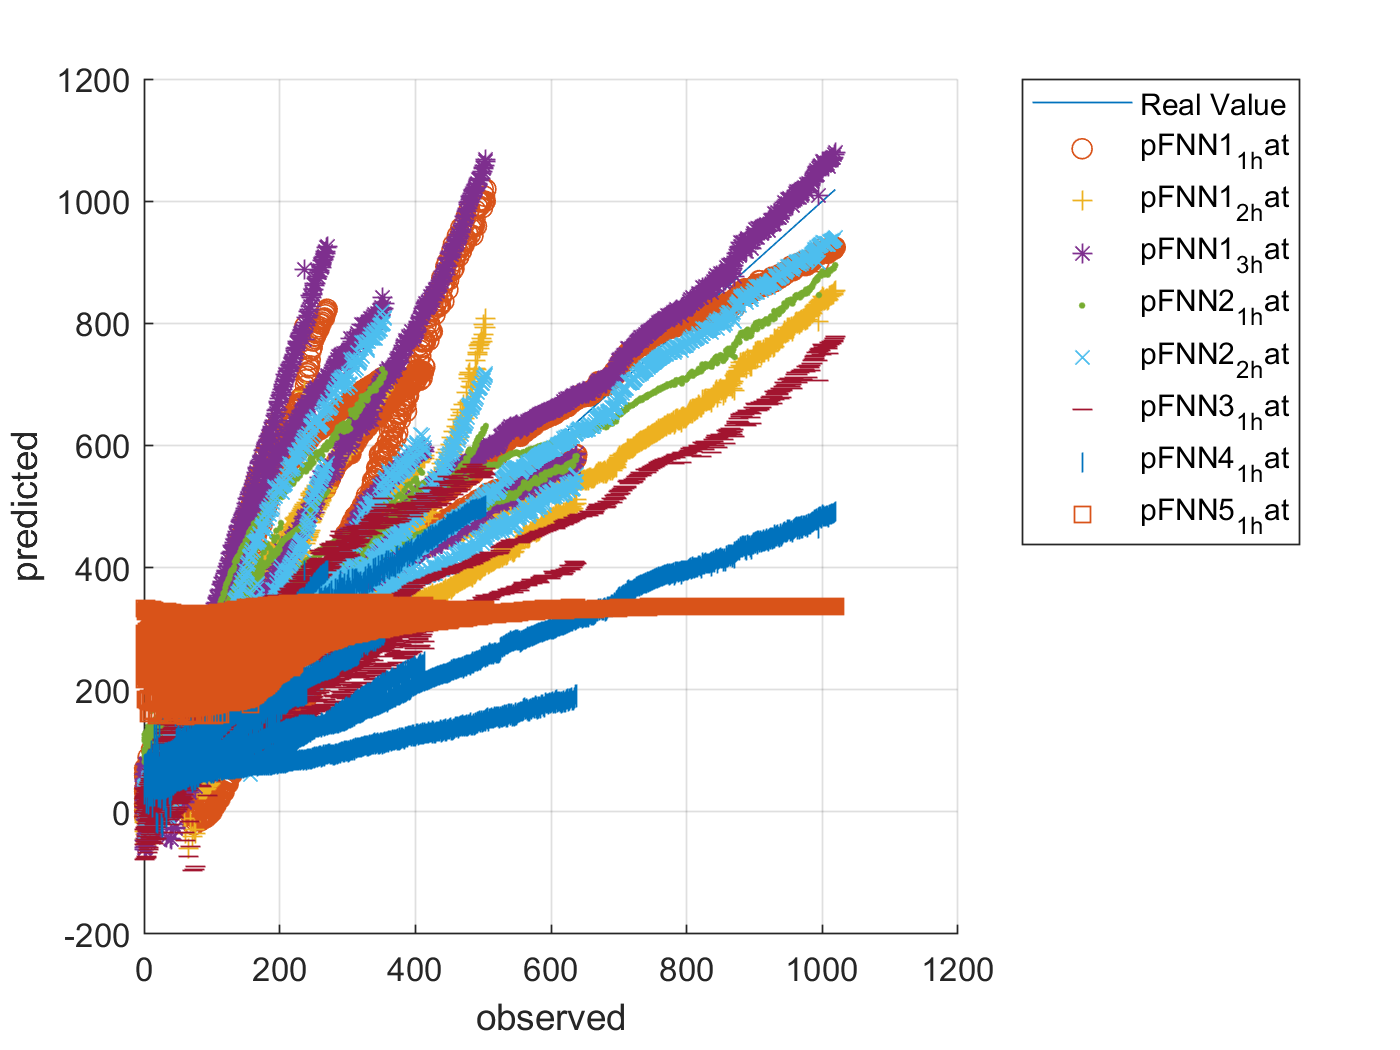


figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pFNN1_1_hat,'o')
plot(ytest,pFNN1_2_hat,'+')
plot(ytest,pFNN1_3_hat,'*')
plot(ytest,pFNN2_1_hat,'.')
plot(ytest,pFNN2_2_hat,'x')
plot(ytest,pFNN3_1_hat,'_')
plot(ytest,pFNN4_1_hat,'|')
plot(ytest,pFNN5_1_hat,'s')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pFNN1_1_hat', ... 
		'pFNN1_2_hat', ...
		'pFNN1_3_hat', ... 	
		'pFNN2_1_hat', ... 
		'pFNN2_2_hat', ... 
		'pFNN3_1_hat', ... 
		'pFNN4_1_hat', ... 
		'pFNN5_1_hat','Location','northeastoutside')

pFNN1_1_self = netFNN1_1(xnorm_Ic_RUL([idxTrainAll idxValidAll], :)');
pFNN1_2_self = netFNN1_2(xnorm_Ic_RUL([idxTrainAll idxValidAll], :)');
pFNN1_3_self = netFNN1_3(xnorm_Ic_RUL([idxTrainAll idxValidAll], :)');
pFNN2_1_self = netFNN2_1(xnorm_Ic_RUL([idxTrainAll idxValidAll], :)');
pFNN2_2_self = netFNN2_2(xnorm_Ic_RUL([idxTrainAll idxValidAll], :)');
pFNN3_1_self = netFNN3_1(xnorm_Ic_RUL([idxTrainAll idxValidAll], :)');
pFNN4_1_self = netFNN4_1(xnorm_Ic_RUL([idxTrainAll idxValidAll], :)');
pFNN5_1_self = netFNN5_1(xnorm_Ic_RUL([idxTrainAll idxValidAll], :)');

ytrain_self = ynorm_Ic_RUL([idxTrainAll idxValidAll], :)*yrate_Ic_RUL + ymin_Ic_RUL;
pFNN1_1_self_hat = pFNN1_1_self * yrate_Ic_RUL + ymin_Ic_RUL;
pFNN1_2_self_hat = pFNN1_2_self * yrate_Ic_RUL + ymin_Ic_RUL;
pFNN1_3_self_hat = pFNN1_3_self * yrate_Ic_RUL + ymin_Ic_RUL;
pFNN2_1_self_hat = pFNN2_1_self * yrate_Ic_RUL + ymin_Ic_RUL;
pFNN2_2_self_hat = pFNN2_2_self * yrate_Ic_RUL + ymin_Ic_RUL;
pFNN3_1_self_hat = pFNN3_1_self * yrate_Ic_RUL + ymin_Ic_RUL;
pFNN4_1_self_hat = pFNN4_1_self * yrate_Ic_RUL + ymin_Ic_RUL;
pFNN5_1_self_hat = pFNN5_1_self * yrate_Ic_RUL + ymin_Ic_RUL;


rmse_pFNN1_1_self_hat = sqrt(mean(( ytrain_self' - pFNN1_1_self_hat ).^2))

rmse_pFNN1_1_self_hat = 151.7337

rmse_pFNN1_2_self_hat = sqrt(mean(( ytrain_self' - pFNN1_2_self_hat ).^2))

rmse_pFNN1_2_self_hat = 108.7448

rmse_pFNN1_3_self_hat = sqrt(mean(( ytrain_self' - pFNN1_3_self_hat ).^2))

rmse_pFNN1_3_self_hat = 122.7385

rmse_pFNN2_1_self_hat = sqrt(mean(( ytrain_self' - pFNN2_1_self_hat ).^2))

rmse_pFNN2_1_self_hat = 133.2605

rmse_pFNN2_2_self_hat = sqrt(mean(( ytrain_self' - pFNN2_2_self_hat ).^2))

rmse_pFNN2_2_self_hat = 108.2937

rmse_pFNN3_1_self_hat = sqrt(mean(( ytrain_self' - pFNN3_1_self_hat ).^2))

rmse_pFNN3_1_self_hat = 134.2716

rmse_pFNN4_1_self_hat = sqrt(mean(( ytrain_self' - pFNN4_1_self_hat ).^2))

rmse_pFNN4_1_self_hat = 192.6971

rmse_pFNN5_1_self_hat = sqrt(mean(( ytrain_self' - pFNN5_1_self_hat ).^2))

rmse_pFNN5_1_self_hat = 197.1336

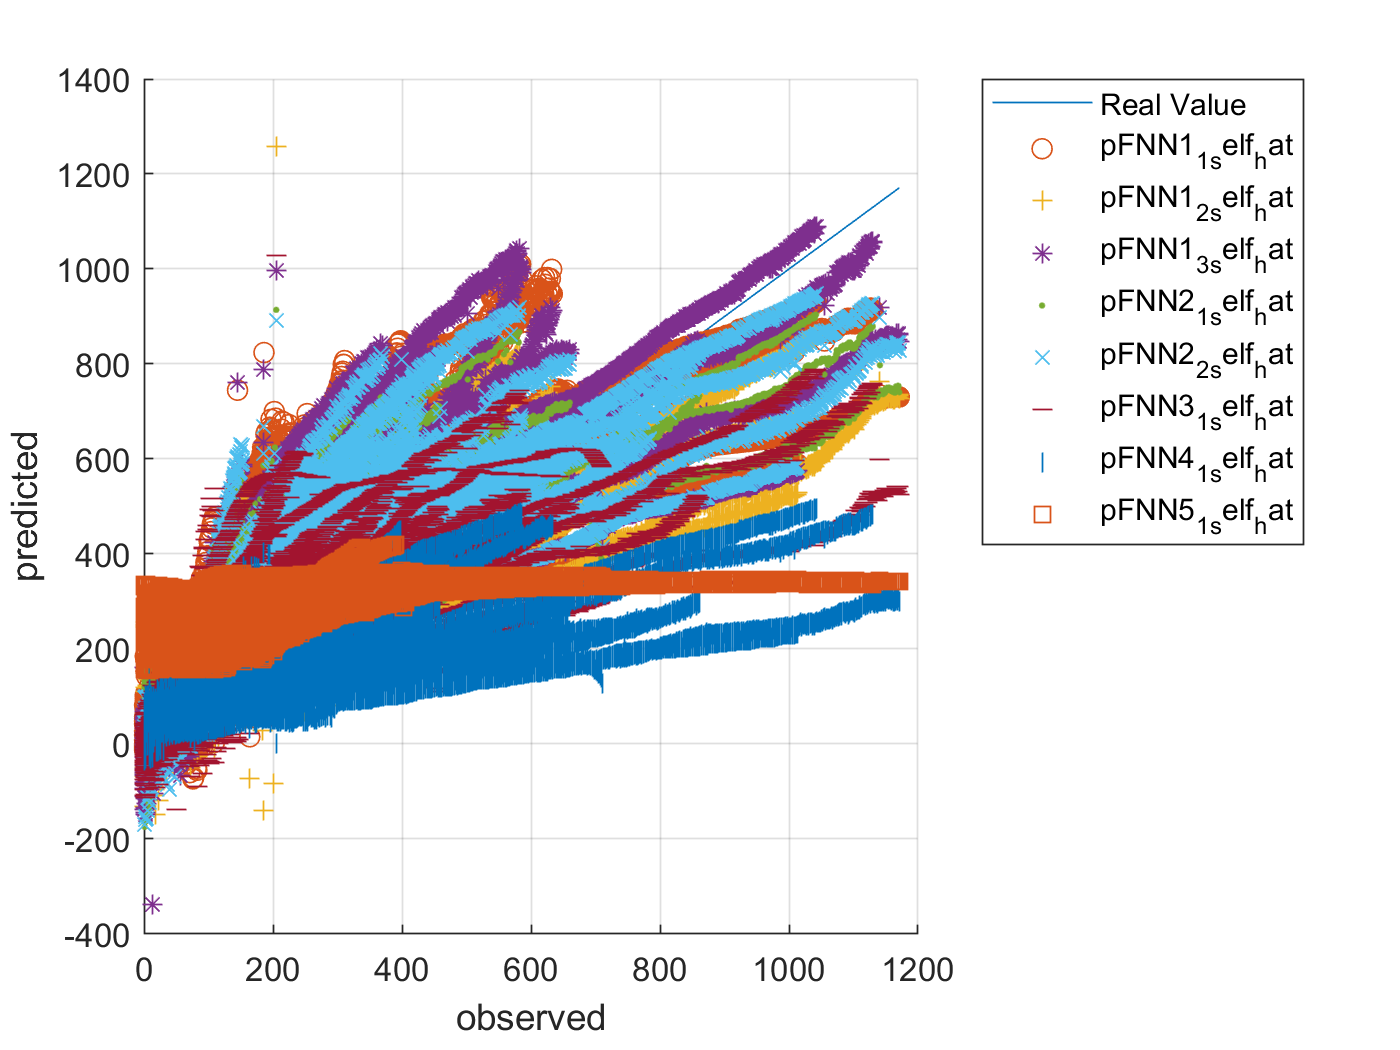



figure, hold on, grid on,
plot(ytrain_self,ytrain_self)
plot(ytrain_self,pFNN1_1_self_hat,'o')
plot(ytrain_self,pFNN1_2_self_hat,'+')
plot(ytrain_self,pFNN1_3_self_hat,'*')
plot(ytrain_self,pFNN2_1_self_hat,'.')
plot(ytrain_self,pFNN2_2_self_hat,'x')
plot(ytrain_self,pFNN3_1_self_hat,'_')
plot(ytrain_self,pFNN4_1_self_hat,'|')
plot(ytrain_self,pFNN5_1_self_hat,'s')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pFNN1_1_self_hat', ... 
		'pFNN1_2_self_hat', ...
		'pFNN1_3_self_hat', ... 	
		'pFNN2_1_self_hat', ... 
		'pFNN2_2_self_hat', ... 
		'pFNN3_1_self_hat', ... 
		'pFNN4_1_self_hat', ... 
		'pFNN5_1_self_hat','Location','northeastoutside')

# CNN

cc_input_size = 20

cc_input_size = 20

cellx = num2cell(xnorm_Ic_RUL(idxTestAll, :)', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);

x_4d = zeros(1, cc_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN2_1 = predict(netCNN2_1, x_4d);
pCNN2_2 = predict(netCNN2_2, x_4d);
%pCNN2_3 = predict(netCNN2_3, x_4d);
%pCNN2_4 = predict(netCNN2_4, x_4d);
pCNN1_1 = predict(netCNN1_1, x_4d);



ytest = ynorm_Ic_RUL(idxTestAll, :)*yrate_Ic_RUL + ymin_Ic_RUL;
pCNN2_1_hat = pCNN2_1 * yrate_Ic_RUL + ymin_Ic_RUL;
pCNN2_2_hat = pCNN2_2 * yrate_Ic_RUL + ymin_Ic_RUL;
%pCNN2_3_hat = pCNN2_3 * yrate_Ic_RUL + ymin_Ic_RUL;
%pCNN2_4_hat = pCNN2_4 * yrate_Ic_RUL + ymin_Ic_RUL;
pCNN1_1_hat = pCNN1_1 * yrate_Ic_RUL + ymin_Ic_RUL;


rmse_pCNN2_1_hat = sqrt(mean(( ytest' - pCNN2_1_hat' ).^2))

rmse_pCNN2_1_hat = single
116.4063

rmse_pCNN2_2_hat = sqrt(mean(( ytest' - pCNN2_2_hat' ).^2))

rmse_pCNN2_2_hat = single
116.6083

%rmse_pCNN2_3_hat = sqrt(mean(( ytest' - pCNN2_3_hat' ).^2))
%rmse_pCNN2_4_hat = sqrt(mean(( ytest' - pCNN2_4_hat' ).^2))
rmse_pCNN1_1_hat = sqrt(mean(( ytest' - pCNN1_1_hat' ).^2))

rmse_pCNN1_1_hat = single
128.8465

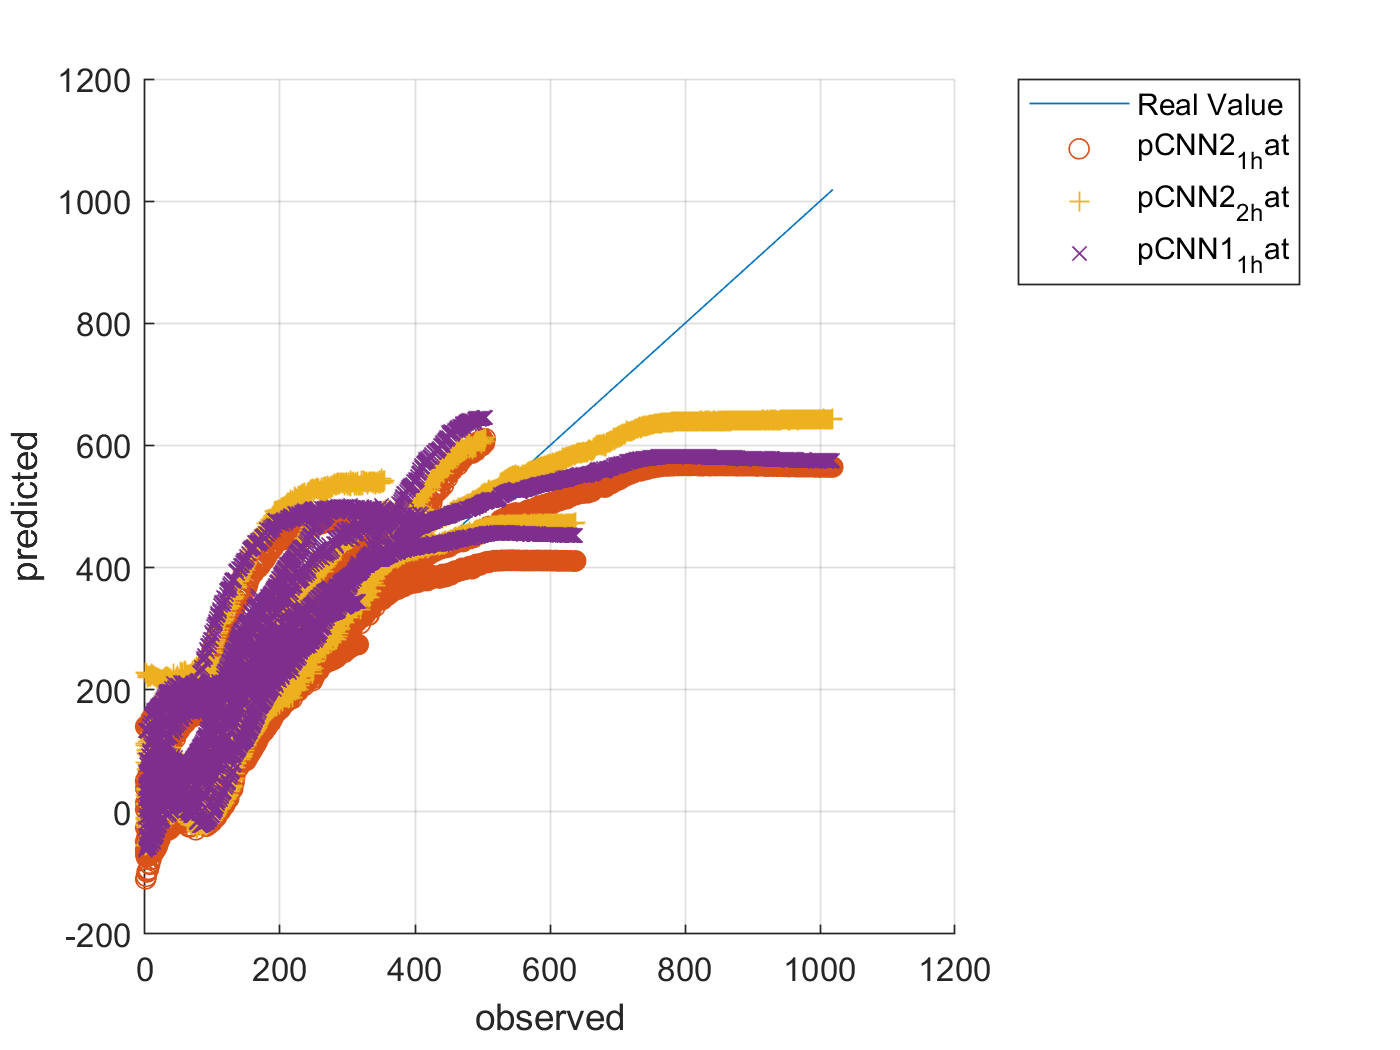




figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pCNN2_1_hat,'o')
plot(ytest,pCNN2_2_hat,'+')
%plot(ytest,pCNN2_3_hat,'*')
%plot(ytest,pCNN2_4_hat,'.')
plot(ytest,pCNN1_1_hat,'x')

hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pCNN2_1_hat', ... 
		'pCNN2_2_hat', ...
		'pCNN1_1_hat','Location','northeastoutside')

cellx_self = num2cell(xnorm_Ic_RUL([idxTrainAll idxValidAll], :)', 1)';
cellx_self = cellfun(@transpose, cellx_self, 'UniformOutput', false);
tbl_self = table(cellx_self);

x_4d_self = zeros(1, cc_input_size, 1, height(tbl_self));
for i = 1:height(tbl_self)
    x_4d_self(:,:,:,i) = tbl_self.cellx_self{i};
end

pCNN2_1_self = predict(netCNN2_1, x_4d_self);
pCNN2_2_self = predict(netCNN2_2, x_4d_self);
%pCNN2_3_self = predict(netCNN2_3, x_4d_self);
%pCNN2_4_self = predict(netCNN2_4, x_4d_self);
pCNN1_1_self = predict(netCNN1_1, x_4d_self);

ytrain_self = ynorm_Ic_RUL([idxTrainAll idxValidAll], :)*yrate_Ic_RUL + ymin_Ic_RUL;
pCNN2_1_self_hat = pCNN2_1_self * yrate_Ic_RUL + ymin_Ic_RUL;
pCNN2_2_self_hat = pCNN2_2_self * yrate_Ic_RUL + ymin_Ic_RUL;
%pCNN2_3_self_hat = pCNN2_3_self * yrate_Ic_RUL + ymin_Ic_RUL;
%pCNN2_4_self_hat = pCNN2_4_self * yrate_Ic_RUL + ymin_Ic_RUL;
pCNN1_1_self_hat = pCNN1_1_self * yrate_Ic_RUL + ymin_Ic_RUL;



rmse_pCNN2_1_self_hat = sqrt(mean(( ytrain_self' - pCNN2_1_self_hat' ).^2))

rmse_pCNN2_1_self_hat = single
119.9734

rmse_pCNN2_2_self_hat = sqrt(mean(( ytrain_self' - pCNN2_2_self_hat' ).^2))

rmse_pCNN2_2_self_hat = single
116.0332

%rmse_pCNN2_3_self_hat = sqrt(mean(( ytrain_self' - pCNN2_3_self_hat' ).^2))
%rmse_pCNN2_4_self_hat = sqrt(mean(( ytrain_self' - pCNN2_4_self_hat' ).^2))
rmse_pCNN1_1_self_hat = sqrt(mean(( ytrain_self' - pCNN1_1_self_hat' ).^2))

rmse_pCNN1_1_self_hat = single
126.5452

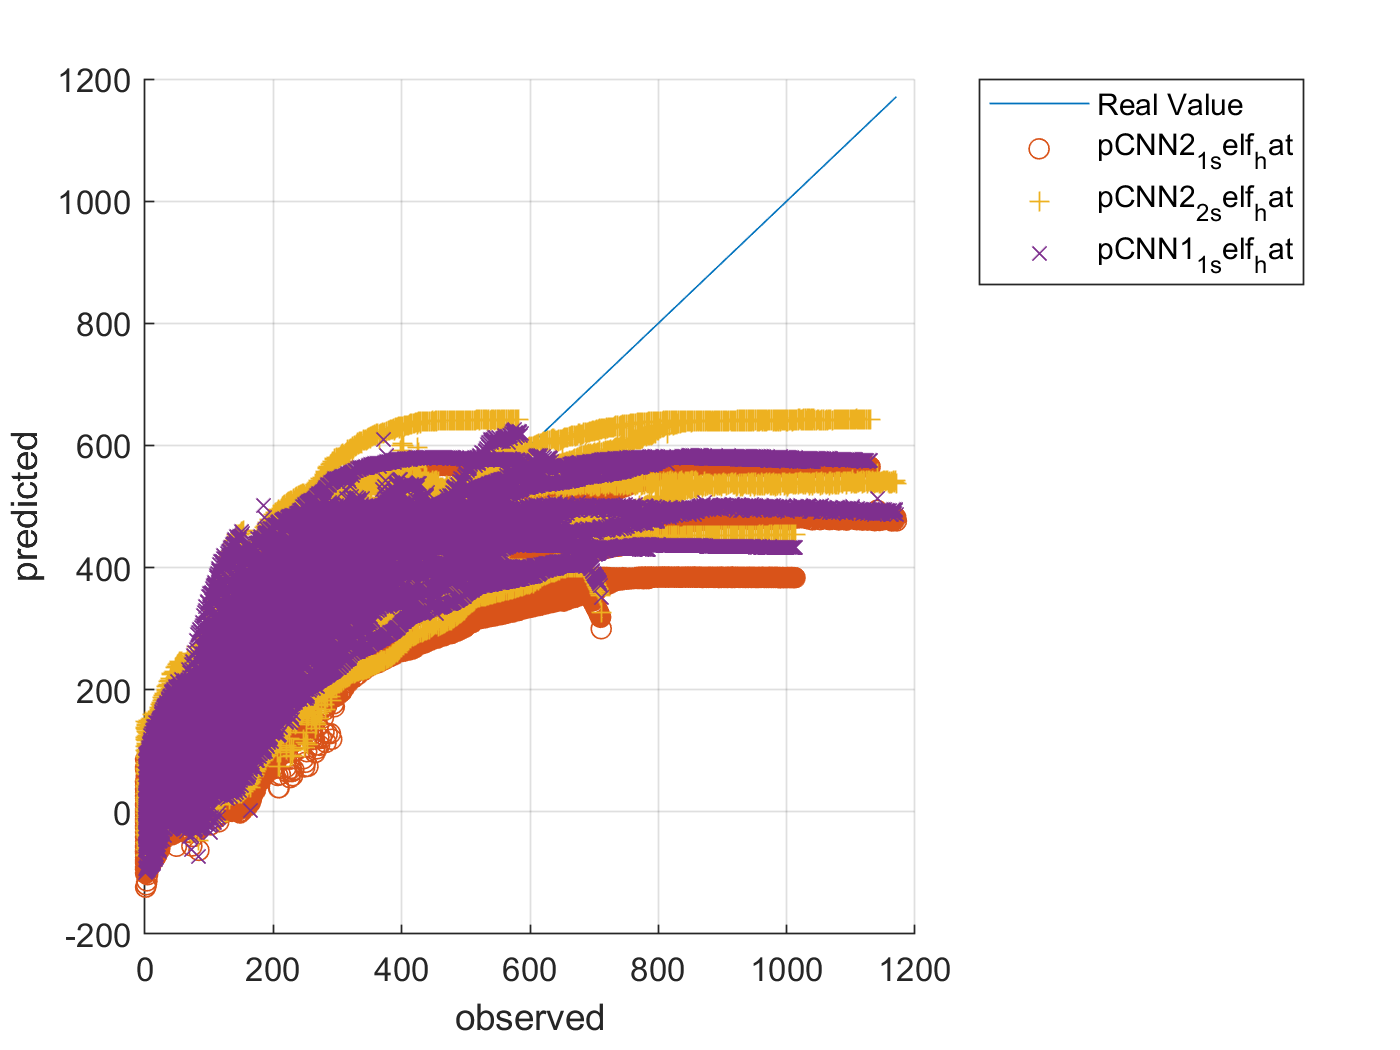




figure, hold on, grid on,
plot(ytrain_self,ytrain_self)
plot(ytrain_self,pCNN2_1_self_hat,'o')
plot(ytrain_self,pCNN2_2_self_hat,'+')
%plot(ytrain_self,pCNN2_3_self_hat,'*')
%plot(ytrain_self,pCNN2_4_self_hat,'.')
plot(ytrain_self,pCNN1_1_self_hat,'x')

hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pCNN2_1_self_hat', ... 
		'pCNN2_2_self_hat', ...
		'pCNN1_1_self_hat','Location','northeastoutside')

pLSTM = cell2mat(predict(netLSTM, num2cell(xnorm_Ic_RUL(idxTestAll, :)', 1)));
pLSTM2 = cell2mat(predict(netLSTM2, num2cell(xnorm_Ic_RUL(idxTestAll, :)', 1)));
ytest = ynorm_Ic_RUL(idxTestAll, :)*yrate_Ic_RUL + ymin_Ic_RUL;
pLSTM_hat = pLSTM * yrate_Ic_RUL + ymin_Ic_RUL;
pLSTM2_hat = pLSTM2 * yrate_Ic_RUL + ymin_Ic_RUL;
rmse_pLSTM_hat = sqrt(mean(( ytest' - pLSTM_hat' ).^2))

rmse_pLSTM_hat = single
139.6387

rmse_pLSTM2_hat = sqrt(mean(( ytest' - pLSTM_hat' ).^2))

rmse_pLSTM2_hat = single
139.6387

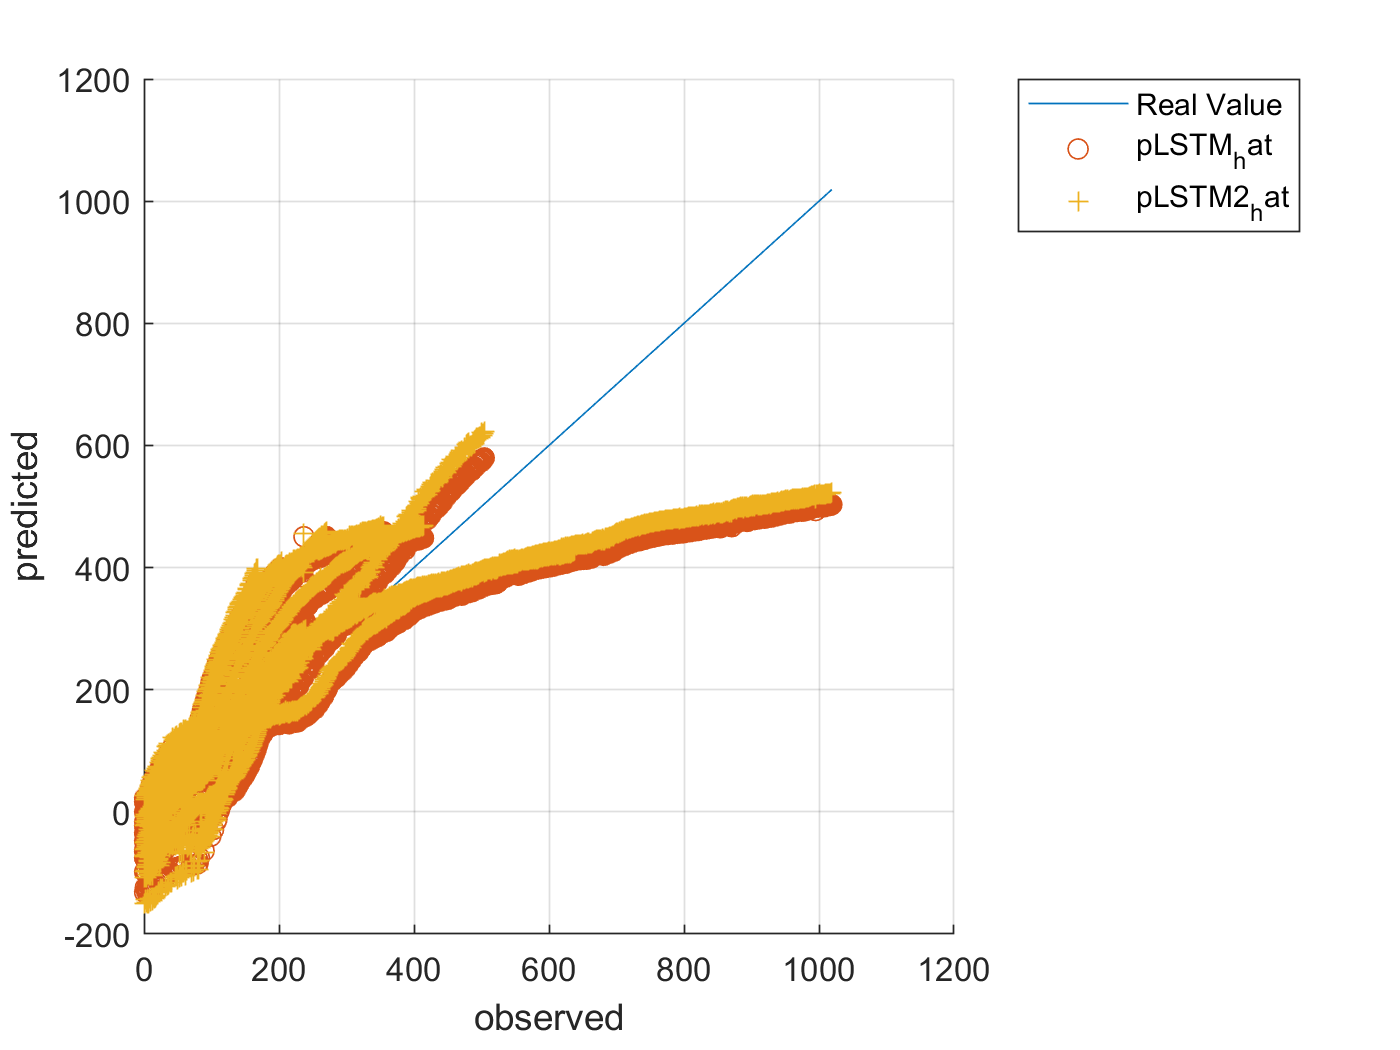



figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pLSTM_hat,'o')
plot(ytest,pLSTM2_hat,'+')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pLSTM_hat', ...
        'pLSTM2_hat','Location','northeastoutside')



pLSTM_self = cell2mat(predict(netLSTM, num2cell(xnorm_Ic_RUL([idxTrainAll idxValidAll], :)', 1)));
pLSTM2_self = cell2mat(predict(netLSTM2, num2cell(xnorm_Ic_RUL([idxTrainAll idxValidAll], :)', 1)));
ytrain_self = ynorm_Ic_RUL([idxTrainAll idxValidAll], :)*yrate_Ic_RUL + ymin_Ic_RUL;
pLSTM_self = pLSTM_self * yrate_Ic_RUL + ymin_Ic_RUL;
pLSTM2_self = pLSTM2_self * yrate_Ic_RUL + ymin_Ic_RUL;
rmse_pLSTM_self_hat = sqrt(mean(( ytrain_self' - pLSTM_self' ).^2))

rmse_pLSTM_self_hat = single
134.6063

rmse_pLSTM2_self_hat = sqrt(mean(( ytrain_self' - pLSTM2_self' ).^2))

rmse_pLSTM2_self_hat = single
133.1613

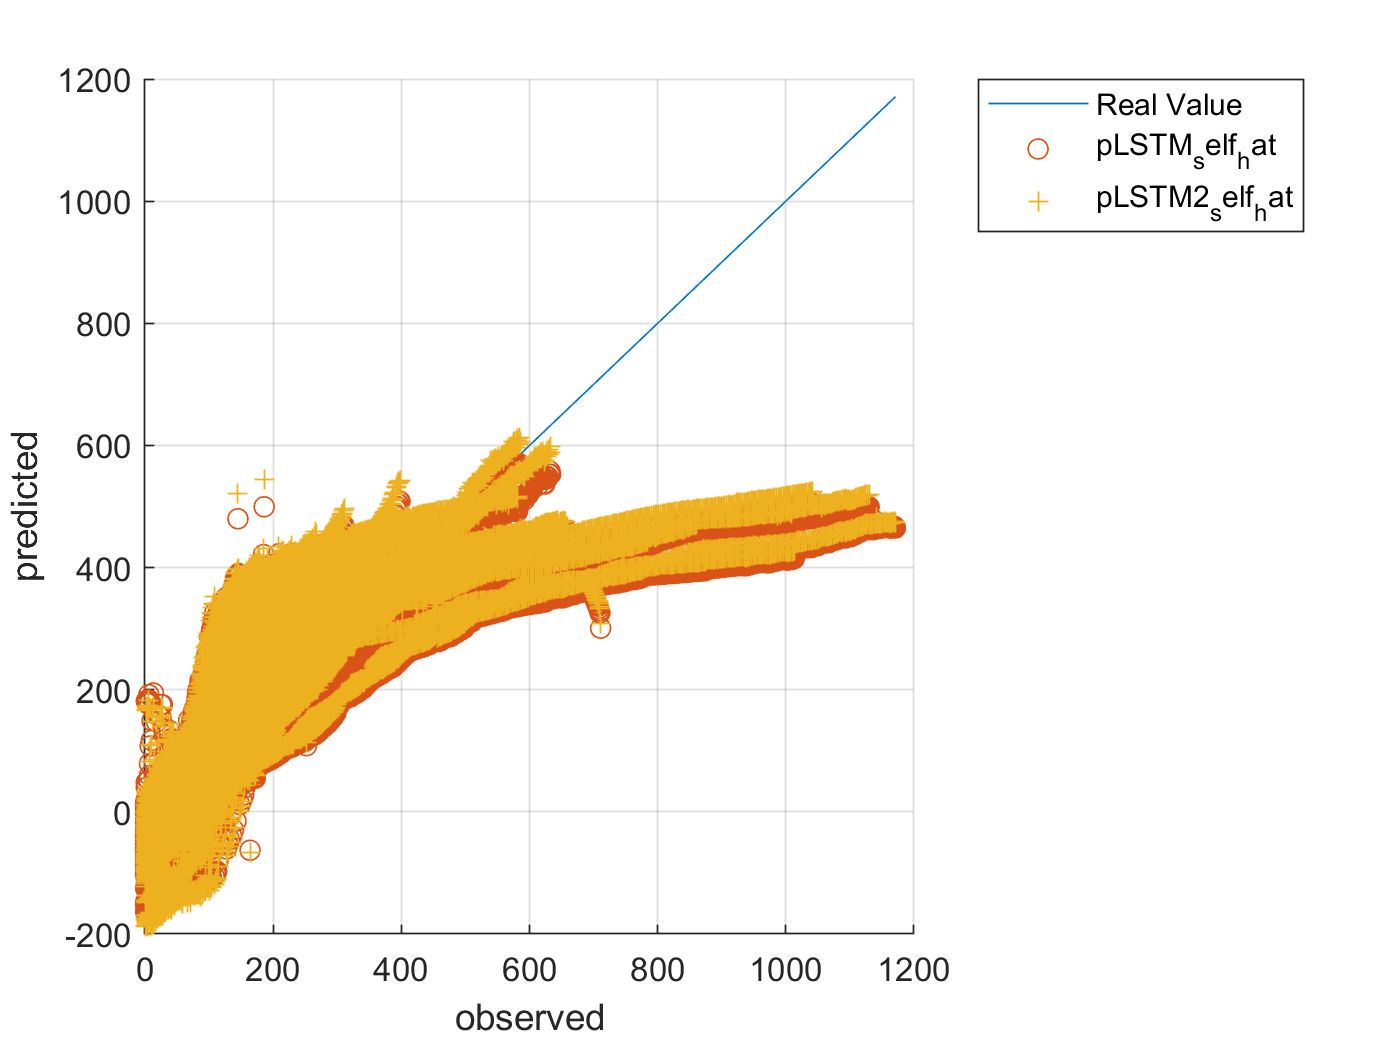


figure, hold on, grid on,
plot(ytrain_self,ytrain_self)
plot(ytrain_self,pLSTM_self,'o')
plot(ytrain_self,pLSTM2_self,'+')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pLSTM_self_hat', ...
        'pLSTM2_self_hat','Location','northeastoutside')